eeg1=strap1.eeg4;
eeg2=strap1.eeg5;
eeg3=strap1.eeg6;
eeg4=strap1.eeg7;

f=length(eeg1)/120;
t=1/f;
t_D=[0:1:length(eeg2)-1]*t;

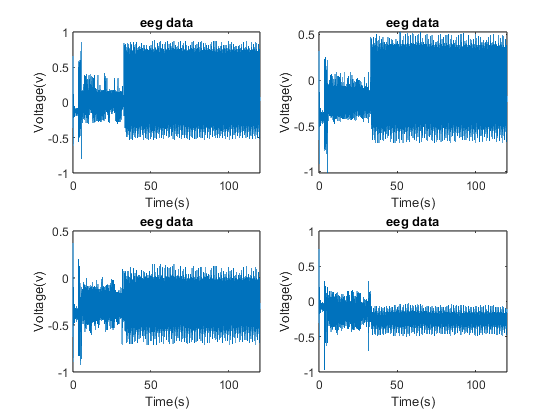

figure;
subplot(2,2,1)
plot(t_D,eeg1)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

subplot(2,2,2)
plot(t_D,eeg2)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,3)
plot(t_D,eeg3)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,4)
plot(t_D,eeg4)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

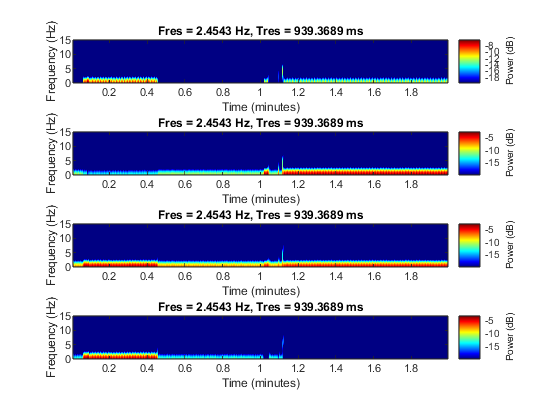

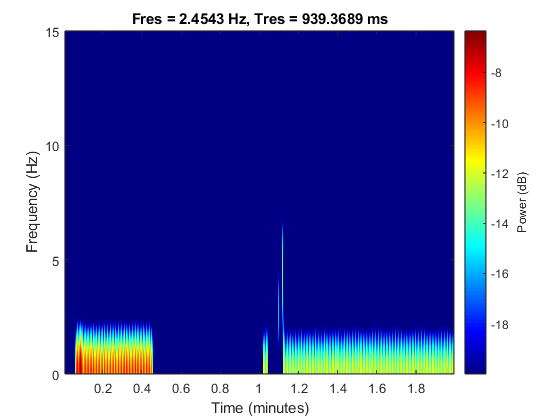

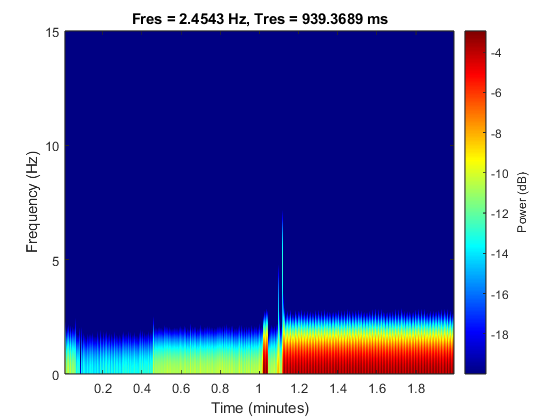

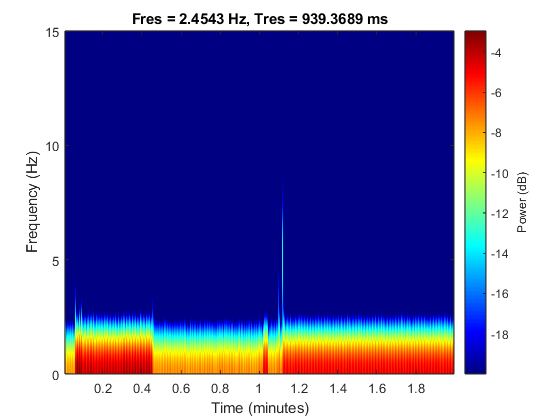

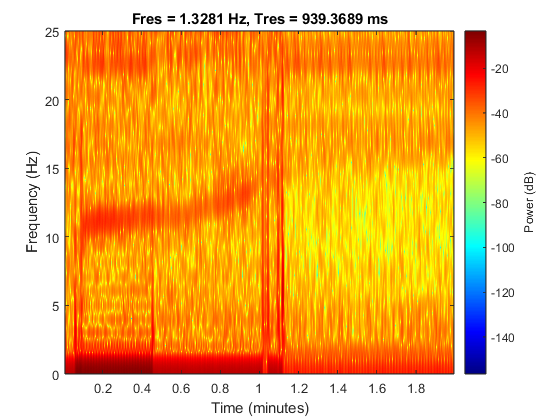

% Smooth input data
eegs1 = smoothdata(eeg1,"movmean",81);


% Display results
clf
plot(eeg1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eegs1,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

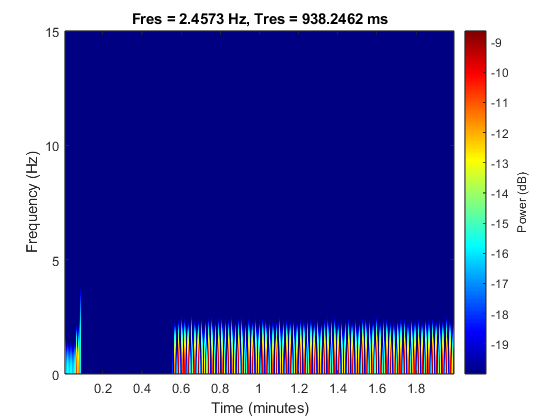

figure;
colormap jet;

pspectrum(eeg1,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

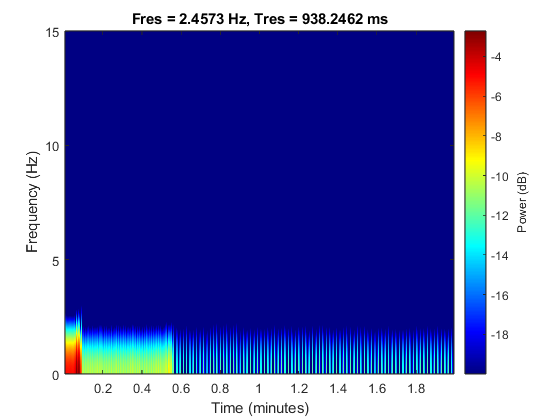

figure;
colormap jet;

pspectrum(eeg2,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

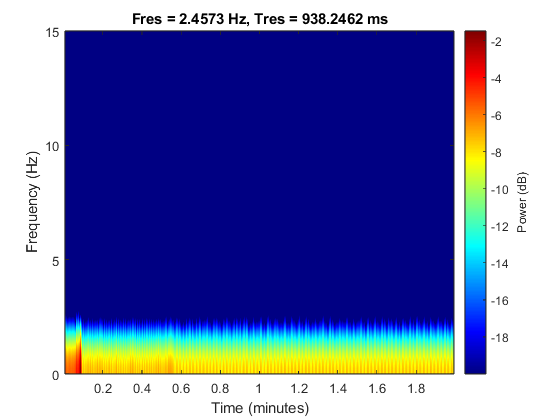

figure;
colormap jet;

pspectrum(eeg3,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

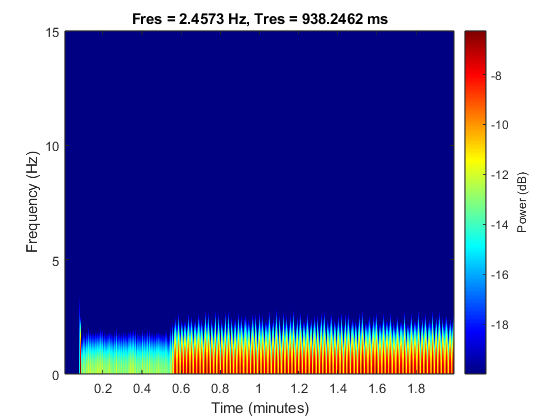

figure;
colormap jet;

pspectrum(eeg4,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)